% Load the CSV data
data_exp_est = readtable('./exp_pose.csv');
timestamp_exp_est = (data_exp_est{:,1}-data_exp_est{1,1});

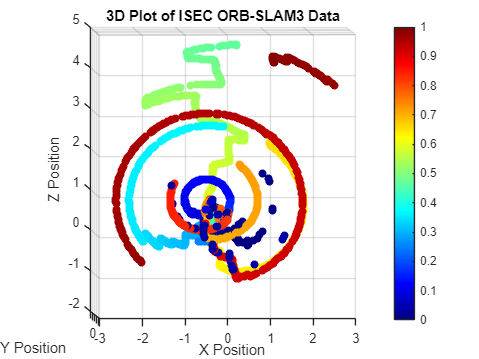

% --------------------- Position Data ------------------- 
% Extract position columns 
x_pose = data_exp_est.Var4; 
y_pose = data_exp_est.Var5; 
z_pose = data_exp_est.Var6; 

% Offset positions to start at (0,0,0) 
x_pose = x_pose - x_pose(1); 
y_pose = y_pose - y_pose(1); 
z_pose = z_pose - z_pose(1);

% Normalize timestamps for coloring 
timestamp_est_norm = (timestamp_exp_est - min(timestamp_exp_est)) / (max(timestamp_exp_est) - min(timestamp_exp_est));

% Plot the 3D trajectory 
figure; 
scatter3(x_pose, y_pose, z_pose, 36, timestamp_est_norm, 'filled'); 
colormap(jet); 
colorbar;
grid on;
xlabel('X Position'); 
ylabel('Y Position'); 
zlabel('Z Position'); 
title('3D Plot of ISEC ORB-SLAM3 Data');